clear; clear path; clc;

format shortG

load ../../data/plantTF.mat

syms s;

Ps

Ps =
 
        200 s + 1e06
  ------------------------
  s^4 + 200 s^3 + 1e06 s^2
 
Continuous-time transfer function.
Model Properties



Tfun = Ps/(1+Ps)

Tfun =
 
                200 s^5 + 1.04e06 s^4 + 4e08 s^3 + 1e12 s^2
  -----------------------------------------------------------------------
  s^8 + 400 s^7 + 2.04e06 s^6 + 4e08 s^5 + 1e12 s^4 + 4e08 s^3 + 1e12 s^2
 
Continuous-time transfer function.
Model Properties



[Num,Den] = tfdata(Tfun);
T = poly2sym(cell2mat(Num),s)/poly2sym(cell2mat(Den),s)

$$T = \frac{200\,s^{5}+1040000\,s^{4}+400000000\,s^{3}+1000000000000\,s^{2}}{s^{8}+400\,s^{7}+2040000\,s^{6}+400000200\,s^{5}+1000001040000\,s^{4}+400000000\,s^{3}+1000000000000\,s^{2}}$$


clPoles = poles(T,s)

$$clPoles = \left(\begin{array}{c} 0.00000000010000039600146016532289295125128+1.0000005000008550019283048819185\,\mathrm{i}\\ 0.00000000010000039600146016532289295087609-1.0000005000008550019283048819185\,\mathrm{i}\\ -100.00000000010000039600146016532-994.98693458709295662696484248496\,\mathrm{i}\\ -100.00000000010000039600146016532+994.98693458709295662696484248496\,\mathrm{i} \end{array}\right)$$

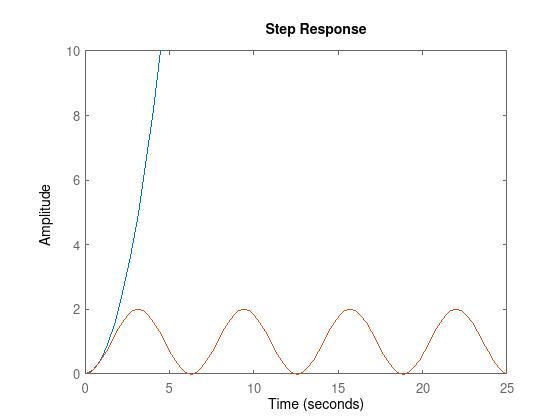


figure(1); clf; hold on; grid on
step(Ps)
step(Tfun)
axis([0 25 0 10])

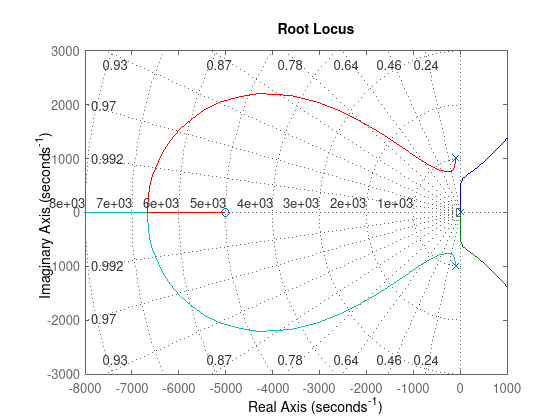


% s = tf([1 0],[0 1])

% ideal = (s-10)/(s^2+a*s+b)
% 
% figure(2); clf; hold on; grid on;
% step(ideal)

figure(2); clf; hold on;
rlocus(Ps)
axis([-8E3 1E3 -3E3 3E3]);
grid on;

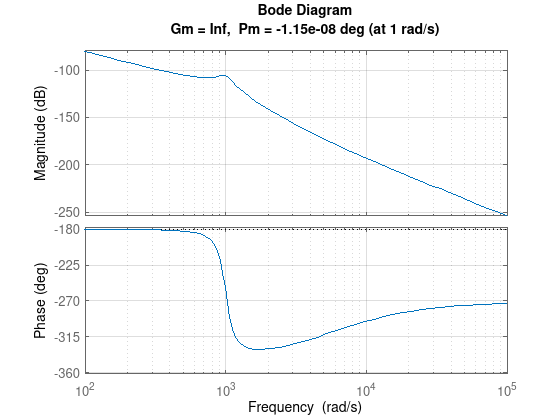


% figure(3); clf; hold on;
% rlocus(Ps)
% axis([-1E-10 1E-10 -1E-20 1E-20]);

[r,ksdensity] = rlocus(Ps);
figure(3);clf;hold on;
margin(Ps); grid on;